clear;
% Parameters
fs = 400; % Control frequency in Hz
dt = 1/fs;
T = 2; % Total simulation time in seconds
t = 0:1/fs:T; % Time vector
w_mea=0.0000;
peak=0.0;
R_mea=0.0;
wrapToPi = @(angle) mod(angle + pi, 2*pi) - pi;
r0xy=50;
r0z=2;
h0=1/100;
c=5;
wb=5;
b1=3*wb;
b2=3*wb^2;
b3=wb^3;
global Kp Kd;
% Kp=[5;5;3];
% Kd=[10;10;10];
global R1
R1=eul2rotm([15,45,50]/180*pi);
Rd = zeros(3, 3, length(t));
for i = 1:length(t)
%     Rd(:, :, i) = eul2rotm([0,sin(2*t(i)),sin(1*t(i))]);
     Rd(:, :, i) = R1;
end

eul=rotm2eul(Rd);
Rd3=eul(:,1);
Rd2=eul(:,2);
Rd1=eul(:,3);

Rd1 = wrapToPi(Rd1);
Rd2 = wrapToPi(Rd2);
Rd3 = wrapToPi(Rd3);

Rd_in= [t', reshape(permute(Rd, [3, 1, 2]), [], 9)];
m=0.688;
J=diag([0.0021 0.0023 0.004]);
% J=diag([0.029 0.029 0.055]);

A=[zeros(3,3),eye(3);zeros(3,6)];
B=[zeros(3,3);eye(3)];
Q=diag([300 300 20 200 200 10]);
R=diag([0.1 0.1 10]);
sys=ss(A,B,eye(6),zeros(6,3));
K2=lqr(sys,Q,R);
% Kp=[30;30;3];
% Kd=[60;60;6];
Kp=diag(K2(:,1:3));
Kd=diag(K2(:,4:6));
% 指定的新极点位置
desired_poles = [-3, -3, -4, -2.5, -3, -2];

% 设计状态反馈控制律
K = place(A, B, desired_poles);

% sim("atti.slx")
sim("sitl_atti.slx")

TD_RD=permute(reshape(TD_RD,[],3,3),[2,3,1]);
TDeul=rotm2eul(TD_RD);
TD3=TDeul(:,1);
TD2=TDeul(:,2);
TD1=TDeul(:,3);

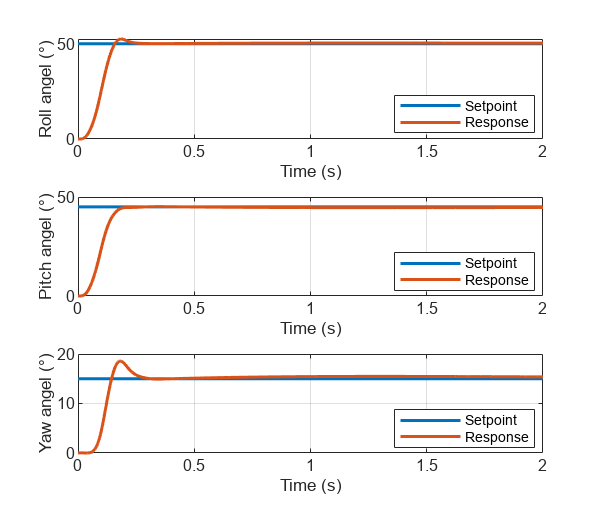


figure
set(groot, 'DefaultLineLineWidth', 1.5);
set(figure, 'Position', [0, 0, 400, 350]); % [左, 下, 宽, 高]
subplot(3,1,1)
plot(t, Rd1 * 180/pi, tout, outa(:,1) * 180/pi)
legend(  'Setpoint','Response', 'Location', 'best');
xlabel('Time (s)'); ylabel('Roll angel (°)');
grid on
subplot(3,1,2)
plot(t, Rd2 * 180/pi, tout, outa(:,2) * 180/pi)
legend(  'Setpoint','Response', 'Location', 'best');
xlabel('Time (s)'); ylabel('Pitch angel (°)');
grid on
subplot(3,1,3)
plot(t, Rd3 * 180/pi, tout, outa(:,3) * 180/pi)
legend(  'Setpoint','Response', 'Location', 'best');
xlabel('Time (s)'); ylabel('Yaw angel (°)');
grid on
saveas(gcf, 'C:\Users\zzy\Desktop\爱沙尼亚\sim_angle.eps', 'epsc');

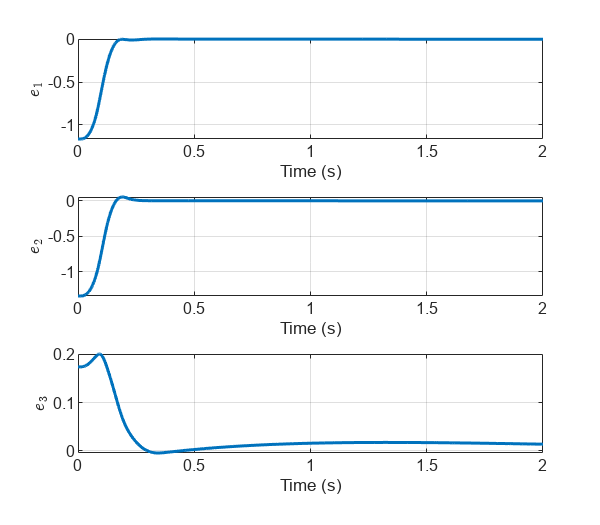


figure
set(figure, 'Position', [0, 0, 400, 350]);
subplot(3,1,1)
plot(tout,e1);
xlabel('Time (s)'); ylabel({'$e_1$'}, 'Interpreter', 'latex');
grid on
subplot(3,1,2)
plot(tout,e2);
xlabel('Time (s)'); ylabel({'$e_2$'}, 'Interpreter', 'latex');
grid on
subplot(3,1,3)
plot(tout,e3);
xlabel('Time (s)'); ylabel({'$e_3$'}, 'Interpreter', 'latex');
grid on
saveas(gcf, 'C:\Users\zzy\Desktop\爱沙尼亚\sim_e.eps', 'epsc');



figure
set(groot, 'DefaultLineLineWidth', 1.0);
set(figure, 'Position', [0, 0, 800, 600]); % [左, 下, 宽, 高]
subplot(3,3,1)
plot(t, Rd1 * 180/pi,tout, TD1 * 180/pi, tout, outa(:,1) * 180/pi)
legend('desired','TD','actual');
xlabel('t'); ylabel('phi/°');

subplot(3,3,2)
plot(t, Rd2 * 180/pi,tout, TD2 * 180/pi, tout, outa(:,2) * 180/pi)
legend('desired','TD','actual');
xlabel('t'); ylabel('theta/°');

subplot(3,3,3)
plot(t, Rd3 * 180/pi,tout, TD3 * 180/pi, tout, outa(:,3) * 180/pi)
legend('desired','TD','actual');
xlabel('t'); ylabel('psi/°');



subplot(3,3,4)
plot(t, wd1 * 180/pi, tout, outw(:,1) * 180/pi)
legend('desired','actual');
xlabel('t'); ylabel('w1/°/s');

subplot(3,3,5)
plot(t, wd2 * 180/pi, tout, outw(:,2) * 180/pi)
legend('desired','actual');
xlabel('t'); ylabel('w2/°/s');

subplot(3,3,6)
plot(t, wd3 * 180/pi, tout, outw(:,3) * 180/pi)
legend('desired','actual');
xlabel('t'); ylabel('w3/°/s');

subplot(3,3,7)
plot(tout,outM(:,1),tout,ul(:,1));
legend('M','ul');
xlabel('t'); ylabel('M1/Nm');

subplot(3,3,8)
plot(tout,outM(:,2),tout,ul(:,2));
legend('M','ul');
xlabel('t'); ylabel('M2/Nm');

subplot(3,3,9)
plot(tout,outM(:,3),tout,ul(:,3));
legend('M','ul');
xlabel('t'); ylabel('M3/Nm');

% 
% figure
% set(figure, 'Position', [0, 0, 800, 600]);
% subplot(2,3,1)
% plot(tout,e1,tout,z1(:,1));
% legend('raw','obs');
% xlabel('t'); ylabel('e1');
% 
% subplot(2,3,2)
% plot(tout,e2,tout,z1(:,2));
% legend('raw','obs');
% xlabel('t'); ylabel('e2');
% 
% subplot(2,3,3)
% plot(tout,e3,tout,z1(:,3));
% legend('raw','obs');
% xlabel('t'); ylabel('e3');
% 
% subplot(2,3,4)
% plot(tout,de1,tout,z2(:,1));
% legend('raw','obs');
% xlabel('t'); ylabel('de1');
% 
% subplot(2,3,5)
% plot(tout,de2,tout,z2(:,2));
% legend('raw','obs');
% xlabel('t'); ylabel('de2');
% 
% subplot(2,3,6)
% plot(tout,de3,tout,z2(:,3));
% legend('raw','obs');
% xlabel('t'); ylabel('de3');
% 
% figure
% set(figure, 'Position', [0, 0, 800, 300]);
% z3=z3*J;
% subplot(1,3,1)
% plot(tout,outn(:,1),tout,z3(:,1))
% legend('actual','obs');
% xlabel('t'); ylabel('noise1');
% subplot(1,3,2)
% plot(tout,outn(:,2),tout,z3(:,2))
% legend('actual','obs');
% xlabel('t'); ylabel('noise2');
% subplot(1,3,3)
% plot(tout,outn(:,3),tout,z3(:,3))
% legend('actual','obs');
% xlabel('t'); ylabel('noise3');